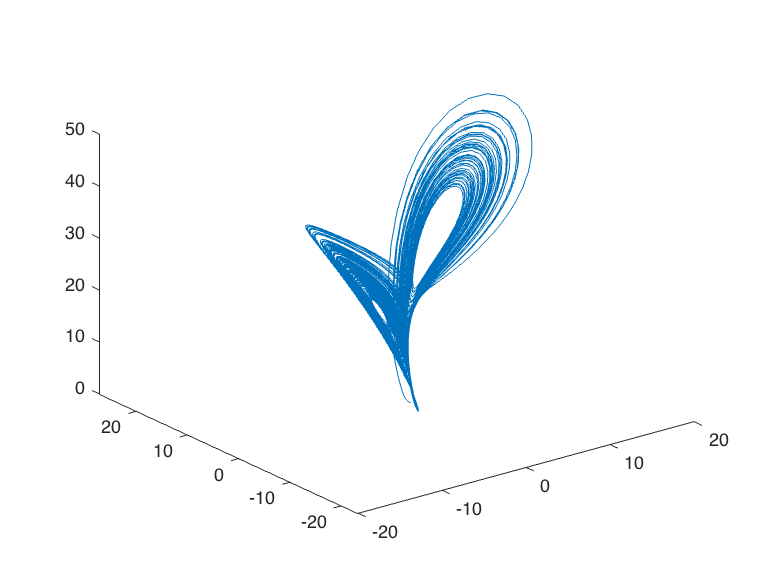

sigma = 10;
beta = 8/3;
rho = 28;
f = @(t,x) [-sigma*x(1) + sigma*x(2); rho*x(1) - x(2) - x(1)*x(3); -beta*x(3) + x(1)*x(2)];
[t,x] = ode45(f,[0 100],[1 1 1]);     
plot3(x(:,1),x(:,2),x(:,3))

## Stabilizing the system

We have the following system:


$$\begin{array}{l}
\frac{\textrm{dx}}{\textrm{dt}}=A\cdot \mathit{\mathbf{x}}+B\cdot \mathit{\mathbf{u}}\\
y=C\cdot \mathit{\mathbf{x}}
\end{array}$$


where: $u\left(t\right)=-k\cdot x\left(t\right)=\left\lbrack \begin{array}{ccc}
k_1  & k_2  & k_3 
\end{array}\right\rbrack \cdot \left\lbrack \begin{array}{c}
x_1 \\
x_2 \\
x_3 
\end{array}\right\rbrack$

Therefore we want to find the values of k that will alter this system bringing it to stability. And it does so the following way:


$$\frac{\textrm{dx}}{\textrm{dt}}=\left(A-B\cdot K\right)\cdot \mathit{\mathbf{x}}$$


In MATLAB we can use the function *place* to calculate the values of k needed to stabilize the system. We can do so the following way:

A = [-sigma sigma 0; rho -1 0; 0 0 -beta];

Acl = A - B*K

Acl =   -20.8404   -2.9132    2.4203
   17.1596  -13.9132    2.4203
  -10.8404  -12.9132   -0.2464



eig(A)

ans =   -22.8277
   11.8277
   -2.6667


B = [1 ; 1; 1]

B =      1
     1
     1


K = place(A,B,[-10,-12,-13])

K =    10.8404   12.9132   -2.4203


## Stiff system simulation

We call a stiff system a system that has two states that change at two very different rates. These systems requires the usage of an appropiate numerical method, with a very small time step.